% transfer function for 3D geophones
% Values for geophones used in projects from December 2019
% Damping Resistor = 9.090 kΩ
% Gs = 27.7 V/(m/s); Ds = 0.7; fs = 4.5 Hz

% Cubes: gain and resulting sensitivity Cv (counts/Volt)
% 4     1.6393e7            
% 16    6.5574e7                 
% in combination with Trillium Compact the sensitivity needs to be multiplied by 1/10
% sensitivity V/(m/s)

Gs = 27.7; 
Cv=6.5574e7;

% Normalization factor
k = 1.0;

% Define poles and zeros
p1 = -19.78 + 20.20i;
p2 = -19.78 - 20.20i;
z1 = 0;
z2 = 0;




**Simulate a velocity seismogramm**

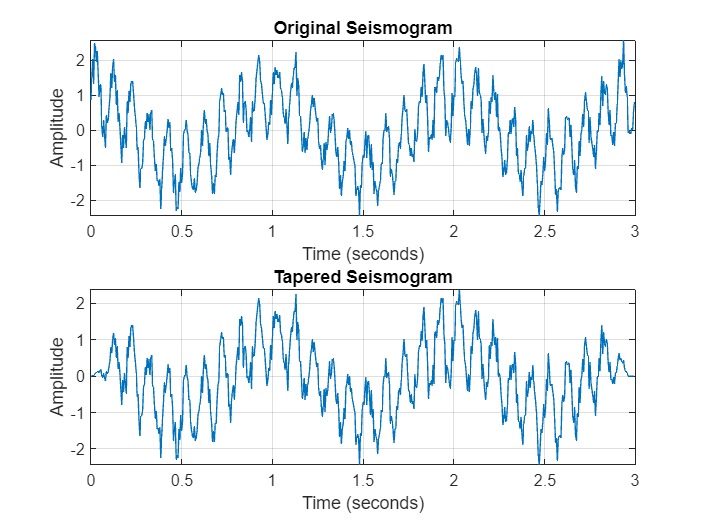

% Parameters
duration = 3; % Duration of the signal in seconds
sampling_rate = 200; % Sampling rate in Hz
t = 0:1/sampling_rate:duration-1/sampling_rate; % Time vector

% Generate a seismic signal: Sum of sine waves + random noise
signal = 1.0 * sin(2 * pi * 10 * t) + 1.0 * cos(2 * pi * 1 * t) + 0.3 * randn(size(t));


% Generate a Tukey window with a smaller fraction for quick transition
% The second parameter controls the fraction of the window that is tapered
% Setting it to a smaller value (e.g., 0.1) for quicker transition to maximum
tukey_ratio = 0.15; % Adjust this to control the speed of transition
window = tukeywin(length(signal), tukey_ratio);

% Apply the window (taper) to the signal
tapered_signal = signal .* window';

% Plotting the original and tapered seismogram
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Seismogram');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, tapered_signal);
title('Tapered Seismogram');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

**Apply transfer functions of geophone and data logger**

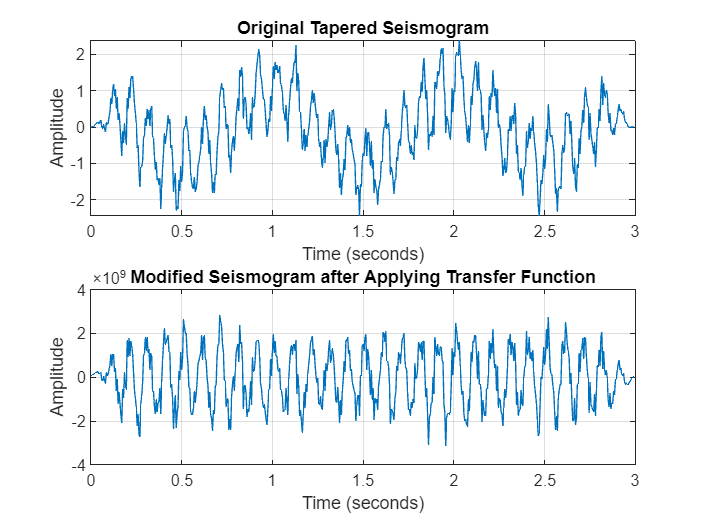

% Fourier Transform of the tapered signal
tapered_signal_fft = fft(tapered_signal);

% Number of points in the signal
n = length(tapered_signal);

% Sampling interval
dt = 1/sampling_rate;

% Initialize the transfer function array to all ones
transfer_function = ones(size(tapered_signal_fft));

% Loop through each index for positive frequencies to generate frequencies and calculate the transfer function
for i = 1:floor(n/2)+1 % Includes Nyquist frequency for even n, excludes for odd n
    % Calculate the frequency at index i
    f = (i-1) / (n*dt);
    
    % Convert to angular frequency
    omega = 2*pi*f;
    
% Compute the transfer function H(s) = k*s^2 / ((s - p1)(s - p2)) for each omega
    s = 1i*omega; % s = j*omega, where j is the imaginary unit
    H = k .* s.^2 ./ ((s - p1) .* (s - p2));
    
    % Include sensitivities to get output in counts (assuming Gs and Cv are defined)
    transfer_function(i) = H*Gs*Cv;
end

% Apply the transfer function to positive frequencies
tapered_signal_fft(1:floor(n/2)+1) = tapered_signal_fft(1:floor(n/2)+1) .* transfer_function(1:floor(n/2)+1);

% Reconstruct the full spectrum using conjugate symmetry in a loop
for i = 2:floor(n/2) % Starts from 2 to exclude DC, goes up to floor(n/2) to handle both even and odd n
    tapered_signal_fft(n-i+2) = conj(tapered_signal_fft(i));
end

% Convert back to the time domain
modified_signal = ifft(tapered_signal_fft);


% Plot the original and modified signals for comparison
figure;
subplot(2,1,1);
plot(t, tapered_signal);
title('Original Tapered Seismogram');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, real(modified_signal)); % Use real() to avoid plotting imaginary part
title('Modified Seismogram after Applying Transfer Function');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

**Apply inverse transfer function to modified signal**

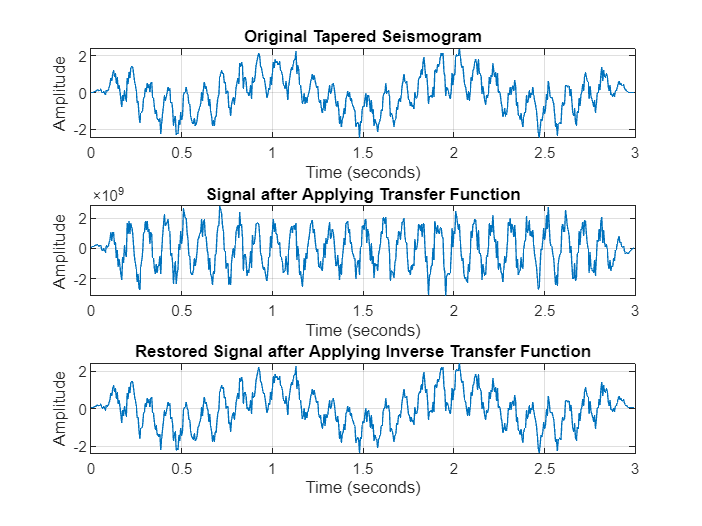

% Initialize the inverse transfer function array
inverse_transfer_function = zeros(size(tapered_signal_fft));

eps=1.e-9;

% Calculate the inverse transfer function for positive frequencies using a loop
for i = 1:floor(n/2)+1 % Handles Nyquist for even n, excludes for odd n
    % To avoid division by zero, ensure that the transfer function is not zero by adding eps
    inverse_transfer_function(i) = 1 / (transfer_function(i) + eps);
end

% Apply the inverse transfer function to positive frequencies
restored_signal_fft = tapered_signal_fft;
restored_signal_fft(1:floor(n/2)+1) = tapered_signal_fft(1:floor(n/2)+1) .* inverse_transfer_function(1:floor(n/2)+1);

% Reconstruct the full spectrum for negative frequencies using conjugate symmetry in a loop
for i = 2:floor(n/2) % Starts from 2 to exclude DC, handles both even and odd n
    % Apply conjugate of the inverse transfer function for positive frequencies to negative ones
    restored_signal_fft(n-i+2) = conj(restored_signal_fft(i));
end

% Convert the spectrum back to the time domain to get the restored signal
restored_signal = ifft(restored_signal_fft);


% Plot the original, modified, and restored signals for comparison
figure;
subplot(3,1,1);
plot(t, tapered_signal);
title('Original Tapered Seismogram');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, real(modified_signal)); % The signal after applying the original transfer function
title('Signal after Applying Transfer Function');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, real(restored_signal)); % Use real() to avoid plotting any minor imaginary part
title('Restored Signal after Applying Inverse Transfer Function');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

**Apply high-pass filter **

% Define your input parameters
seismogram = real(restored_signal); % (your seismogram data here)
Fs = sampling_rate; % Sampling rate in Hz (example value)
n = 4; % Order of the Butterworth filter (example value)

% Apply the high-pass filter
Fc = 4.0; % Cutoff frequency in Hz (example value)
filtered_seismogram_high = applyHighPassFilter(seismogram, Fs, Fc, n);
% then Apply the high-pass filter
Fc = 15.0; % Cutoff frequency in Hz (example value)
filtered_seismogram_high_low = applyLowPassFilter(filtered_seismogram_high, Fs, Fc, n)

filtered_seismogram_high_low =     0.0097    0.0134    0.0191    0.0266    0.0350    0.0427    0.0467    0.0440    0.0313    0.0066   -0.0307   -0.0789   -0.1339   -0.1890   -0.2360   -0.2659   -0.2703   -0.2428   -0.1806   -0.0851    0.0372    0.1752    0.3139    0.4366    0.5265    0.5693    0.5554    0.4813    0.3503    0.1723   -0.0368   -0.2566   -0.4646   -0.6379   -0.7562   -0.8039   -0.7719   -0.6589   -0.4717   -0.2253    0.0581    0.3507    0.6218    0.8407    0.9808    1.0227    0.9573    0.7878    0.5299    0.2103


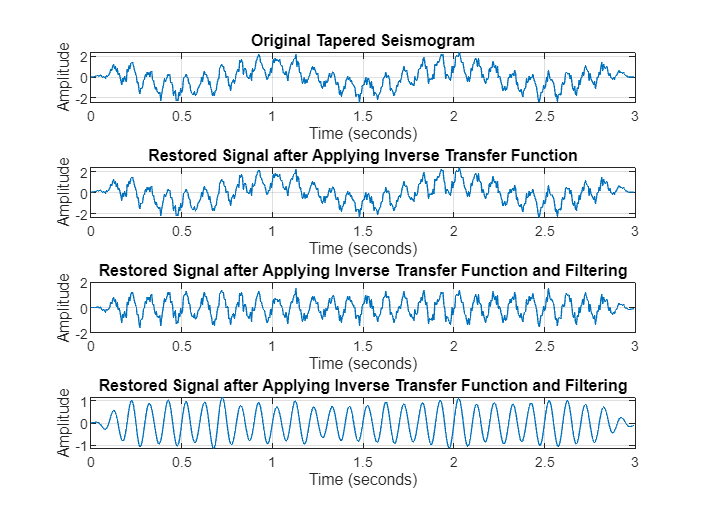


figure;
subplot(4,1,1);
plot(t, tapered_signal);
title('Original Tapered Seismogram');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(4,1,2);
plot(t, real(restored_signal)); % Use real() to avoid plotting any minor imaginary part
title('Restored Signal after Applying Inverse Transfer Function');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(4,1,3);
plot(t, filtered_seismogram_high); %
title('Restored Signal after Applying Inverse Transfer Function and Filtering');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(4,1,4);
plot(t, filtered_seismogram_high_low); %
title('Restored Signal after Applying Inverse Transfer Function and Filtering');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

**Transfer function only**

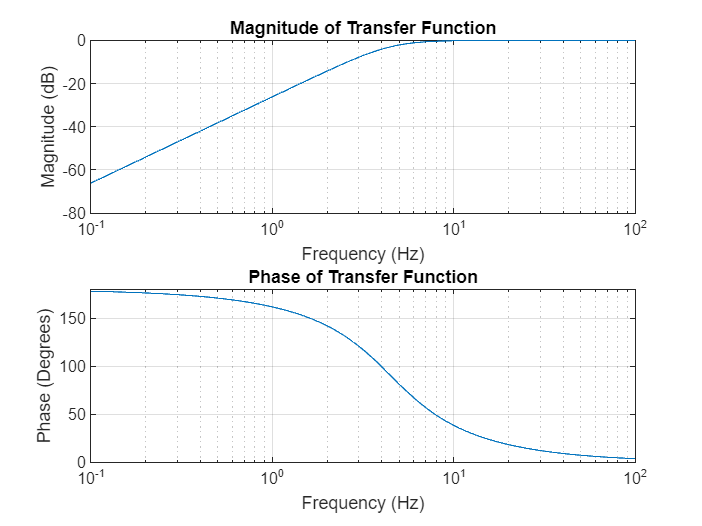


% from counts to m/s: 
% vel=raw*(1/Cv)*(1/Gs)*(1/tf_f);

% Define the frequency range for plotting
f = logspace(log10(0.1), log10(100), 500); % 500 points from 0.1 to 100 Hz
omega = 2*pi*f; % Convert to angular frequency

% Compute the transfer function H(s) = k*s^2 / ((s - p1)(s - p2)) for each omega
s = 1i*omega; % s = j*omega, where j is the imaginary unit
H = k .* s.^2 ./ ((s - p1) .* (s - p2));

% Compute magnitude and phase
magnitude = abs(H);
phase = angle(H) * (180/pi); % Convert phase to degrees

% Plot magnitude and phase on a logarithmic frequency scale
figure;
subplot(2,1,1); % Magnitude plot
semilogx(f, 20*log10(magnitude)); % Convert magnitude to dB with 20*log10
grid on;
title('Magnitude of Transfer Function');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2); % Phase plot
semilogx(f, phase);
ylim([0 180])
grid on;
title('Phase of Transfer Function');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');